%Automated Tracking

%the inital selected st needs to be grabbed
%from area select button
%the current slider value needs to be grabbed
%Need a new button to ask how many frames to be tracked
%or to what end frame


%Load data (Only needs to be done once)
clear
close all %to make sure only the data from this time is shown
%select file
disp('Select -mat file containing ultrasound data\n')

Select -mat file containing ultrasound data\n


fil = uigetfile;            % open dialog box to choose file
data = load(fil);           % load file into struct
%change from struct to 3D matrix
names=fieldnames(data); %extract names of each frame
len=length(names); %find # of frames
[r, c]=size(eval(['data.' names{1}])); %find size of each matrix
mat=zeros(r,c,len); %preallocate
for i=1:len
    mat(:,:,i)=eval(['data.' names{i}]); %enter frame information
end
fprintf([fil ' loaded\n']) %tell user file loaded

n_rmed_2-2.mat loaded


clear i data names %clear variables no longer needed
%convert from RF to amplitude
htf=zeros(r,c,len); %preallocate
for i=1:len
    htf(:,:,i)=hilbert(mat(:,:,i)); %find hilbert transform of each frame
end
hamp=abs(htf); %hamp is the analytic envelope
ctr=5; %compression parameter
amp=20*log10(hamp/ctr); %amplitude in dB

%Create Kernal and St
%For Gui, import the st and create the kn using it
x1 = 103; y1 = 499; w = 50; h = 450;
initstate = [x1, y1, w, h];
st = state(initstate);
% Put things together in a struct, and check the integrity
%search range
sX=10;
sY=20;
%how much of the ROI to search
rX=h/2;
cY=w/2;
method = [sX, sY, rX, cY];
kn = kernel(method,st);

%Pick starting frame and the Last frame to check
%(or how many frames to track for, idk)
%take initframe from current slider
%Have a seperate entry button for the gui for end frame (or # of frames to track)
initframe = 1;
endframe = 13;
matrix_meanu=0;
matrix_meanv=0;

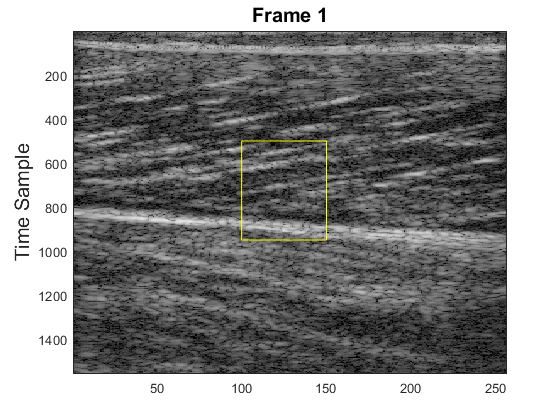

%display first frame image
h=figure;
i1=image(amp(:,:,initframe));
colormap(gray)
fs=num2str(initframe);
title(['Frame ' fs],'FontSize',15)
ylabel('Time Sample','FontSize',15)

rectangle('Position',initstate,'EdgeColor','y')
    

% Cycles through creating new ROI's to track the movement of the inital region
%without having high sX and sY values to track
%Tracks current roi/frame to currentframe+1 rather than initframe to +1,+2,+3 and etc.
fig=figure;
for i= initframe:(endframe-1)
    disp(i)
    if i==initframe
       %generates the Target and template
        x1 = 100; y1 = 500; w = 50; h = 450;
        initstate = [x1, y1, w, h];
        st = state(initstate);
        templ= mat(:,:,i);
        tar= mat(:,:,i+1);
        data = NCorrEst(templ,tar,st,kn);
        %initalizes the mean u and v vectors for later
        %statistical use
        Cart_meanu_vec=zeros(length(initframe:endframe)-1,1);
        Cart_meanv_vec=zeros(length(initframe:endframe)-1,1);
        %{
        h=figure;
        i1=image(amp(:,:,initframe));
        colormap(gray)
        hold on
        fs=num2str(initframe);
        title(['Frame ' fs],'FontSize',15)
        ylabel('Time Sample','FontSize',15)
        rectangle('Position',initstate,'EdgeColor','y')
        %}
        
    else
        %alters the ROI depending on how the movement from the last frame
        x1=round(x1 + Cart_meanu);
        y1=round(y1 + Cart_meanv);
        %size of region of interest remains the same
        initstate = [x1, y1, w, h];
        st = state(initstate);
        %method stays same
        kn = kernel(method,st);
        %generates the Target and template
        templ= mat(:,:,i);
        tar= mat(:,:,i+1);
        data = NCorrEst(templ,tar,st,kn);
        %rectangle('Position',initstate,'EdgeColor','y')
    end
    % Create the quiver
    qdata=quiver(data.v, data.u);
    %disp(["sX " sX "sY " sY] )
    title(['quiver of Temp: ' num2str(i) ' to Tar: ' num2str(i+1)])
    %Generates the mean u and v vectors
    fakeu=zeros(size(data.v));
    fakev=fakeu;
    midx=round(rX/2);
    midy=round(cY/2);
    
    nonz_u= data.u((data.u ~= 0));
    matrix_meanu=mean(nonz_u);
    disp(["meanu:" matrix_meanu])
    
    nonz_v= data.v((data.v ~= 0));
    matrix_meanv=mean(nonz_v);
    disp(["meanv:" matrix_meanv])
    
    %Middle of figure is first mean vec and
    %decending from there is +1
    fakeu(midx+i,midy)=matrix_meanu;
    fakev(midx+i,midy)=matrix_meanv;
    Cart_meanu=matrix_meanv;
    Cart_meanv=matrix_meanu;
    
    Cart_meanu_vec(i)=Cart_meanu;
    Cart_meanv_vec(i)=Cart_meanv;
    %plotting the mean vector of the entire ROI
    hold on
    qdata2=quiver(fakev,fakeu);
    qdata2.LineWidth=3;
    qdata2.AutoScaleFactor=9;
    qdata2.MaxHeadSize=7;
    
end

     1



    "meanu:"    "-0.69526"



    "meanv:"    "0.54649"



     2



    "meanu:"    "-0.88924"



    "meanv:"    "1.0654"



     3



    "meanu:"    "-1.2027"



    "meanv:"    "1.1464"



     4



    "meanu:"    "-1.5197"



    "meanv:"    "1.9565"



     5



    "meanu:"    "-1.7036"



    "meanv:"    "2.9725"



     6



    "meanu:"    "-1.5537"



    "meanv:"    "4.4293"



     7



    "meanu:"    "-1.2598"



    "meanv:"    "5.6702"



     8



    "meanu:"    "-1.8339"



    "meanv:"    "7.5789"



     9



    "meanu:"    "-2.3754"



    "meanv:"    "9.3416"



    10



    "meanu:"    "-3.8847"



    "meanv:"    "8.5112"



    11



    "meanu:"    "-3.3042"



    "meanv:"    "5.9939"



    12



    "meanu:"    "-3.6"



    "meanv:"    "6.9447"



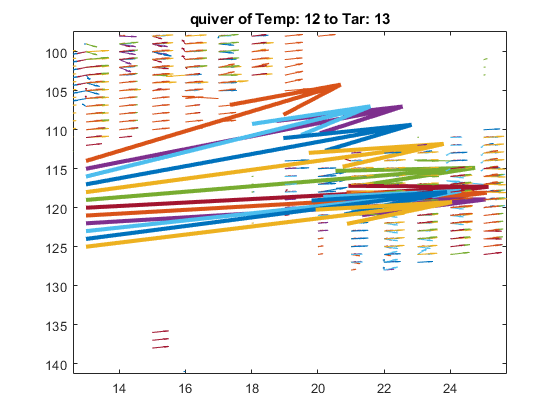

%need to reverse the graph after all objects have been added
set(gca,'Ydir','reverse')